clc;
clear;

# CCD-Algorithmus

1. (**Roh)daten** haben

filename = 'acceleration_log.txt';

% Kommas zu Punkten ersetzen (ohne Semikolons zu beeinflussen)
rawText = fileread(filename);                         % Originaltext lesen
cleanText = regexprep(rawText, '(?<=\d),(?=\d)', '.');% Nur Kommas zwischen Ziffern ersetzen

tempFilename = 'temp_log.txt';                        % Temporäre Datei
fid = fopen(tempFilename, 'w');                       % Datei zum Schreiben öffnen
fwrite(fid, cleanText);                               % Bereinigten Text schreiben
fclose(fid);                                          % Datei schließen

data = readmatrix(tempFilename, 'Delimiter', ';');

% Struktur erzeugen
accelerationX     = data(:,1);
accelerationY     = data(:,2);
accelerationZ     = data(:,3);
accelerationTotal = data(:,4);
t                 = data(:,5);

clear filename tempFilename data fid rawText cleanText;

% Datenbereinigung 1: Bei gleicher Zeit mehrere Werte -> ?:
% nochmals Wert bei gleichem Zeitwert -> Mittelwert machen mit 2 werten -> nochmals Wert mit gleichem Zeitwert -> Mittelwert mit 3 werten -> ...
n = 2;
while n <= length(t)
    if t(n) == t(n-1)
        % falsche/ungenaue Gewichtung bei drei oder mehr Werten
        accelerationX(n-1) = 0.5 * (accelerationX(n-1) + accelerationX(n));
        accelerationY(n-1) = 0.5 * (accelerationY(n-1) + accelerationY(n));
        accelerationZ(n-1) = 0.5 * (accelerationZ(n-1) + accelerationZ(n));
        accelerationTotal(n-1) = 0.5 * (accelerationTotal(n-1) + accelerationTotal(n));

        % Entferne Eintrag n (weil n-1 wurde aktualisiert)
        t(n) = [];
        accelerationX(n) = [];
        accelerationY(n) = [];
        accelerationZ(n) = [];
        accelerationTotal(n) = [];
        % kein n++, weil Liste kürzer wurde
    else
        n = n + 1;  % Nur wenn keine Löschung, zum nächsten Index
    end
end

% Datenbereinigung 2: Zeitinkonsistenzen: "Zeitbrüche"
t_break = [];
for n = 2:length(t)
    if t(n)<t(n-1)
        t_break(end+1) = n;
    end
end
t = t(t_break(end):end);
accelerationX = accelerationX(t_break(end):end);
accelerationY = accelerationY(t_break(end):end);
accelerationZ = accelerationZ(t_break(end):end);
accelerationTotal = accelerationTotal(t_break(end):end);

2. **Filter**

hp_filter = false;
% Hochpassfilter zum filtern der Erdbeschleunigung

if hp_filter
% Filterauswahl als Dropdown
% Filterordnung etc als slider

end

filter1 = false;
% (unsinniges) Bandpassfilterbeispiel

if filter1
    % Sampling-Frequenz (z. B. 100 Hz)
    Fs = 100;
    
    % Bandpass-Grenzfrequenzen in Hz
    f_low = 1;
    f_high = 10;
    
    % Normalisierte Grenzfrequenzen
    Wn = [f_low f_high] / (Fs / 2);
    
    % Filter-Order (je höher, desto schärfer – aber auch rechenintensiver)
    order = 100;
    
    % FIR-Bandpassfilter entwerfen mit Fenster-Methode
    bpFilter = fir1(order, Wn, 'bandpass');
    
    % Gefilterte Daten berechnen
    filteredAcceleration = filter(bpFilter, 1, accelerationTotal);

end

songCheeOh = true;
% y[n] = ((1 - b) · x[n - 1]) + (b · x[n])  Gl3 "weighted smoothing" (TP-Filter)

if songCheeOh
    % Parameter
    b = 0.7;  % Glättungsfaktor (zwischen 0 und 1)
    
    % Ursprüngliche Daten
    x = accelerationTotal;
    
    % Initialisierung des Ergebnis-Vektors
    y = zeros(size(x));
    y(1) = x(1);  % Anfangswert übernehmen
    
    % Rekursive Berechnung
    for n = 2:length(x)
        y(n) = (1 - b) * x(n - 1) + b * x(n);
    end
    
    % Ergebnis in Struct speichern
    filteredAcceleration = y;
end

3. **Integration** -> numerisch (eine von mehreren Möglichkeiten wählen, z.B. Trapez)

% Ursprüngliche Daten 
x = filteredAcceleration;

% Initialisierung des Ergebnis-Vektors
y = zeros(size(x)-1);

% Rekursive Berechnung
for n = 1:length(x)-1
    y(n) = 0.5 *( x(n) + x(n+1) ) * (t(n+1)-t(n)) ;
end
t_mid_velocity = 0.5 * (t(1:end-1) + t(2:end));



% Ergebnis in Struct speichern
velocity = y;

4. **Filter**, z.B.: y[n] = a · (y[n - 1] + x[n] + x[n - 1]) Gl4 "transient components emphasising" (HP-Filter)

% Parameter
a = 0.9;  % Faktor (zwischen 0 und 1)

% Ursprüngliche Daten 
x = velocity;

% Initialisierung des Ergebnis-Vektors
y = zeros(size(x));
y(1) = x(1);  % Anfangswert übernehmen

% Rekursive Berechnung
for n = 2:length(x)
    y(n) = a * (y(n - 1) + x(n) + x(n - 1));
end

% Ergebnis in Struct speichern
filteredVelocity = y;

5. **Integration**

% Ursprüngliche Daten 
x = filteredVelocity;

% Initialisierung des Ergebnis-Vektors
y = zeros(size(x)-1);

% Rekursive Berechnung
for n = 1:length(x)-1
    y(n) = 0.5 *( x(n) + x(n+1) ) * (t(n+1)-t(n)) ;
end
t_mid_segment = 0.5 * (t_mid_velocity(1:end-1) + t_mid_velocity(2:end));


% Ergebnis in Struct speichern
segment = y;

6. **Filter**, z.B.: y[n] = a · (y[n - 1] + x[n] + x[n - 1])  Gl4 "transient components emphasising" (HP-Filter)

% Parameter
a = 0.9;  % Faktor (zwischen 0 und 1)

% Ursprüngliche Daten 
x = segment;

% Initialisierung des Ergebnis-Vektors
y = zeros(size(x));
y(1) = x(1);  % Anfangswert übernehmen

% Rekursive Berechnung
for n = 2:length(x)
    y(n) = a * (y(n - 1) + x(n) + x(n - 1));
end

% Ergebnis in Struct speichern
filteredSegment = y;

7. **Peak** detection -> max(...) & min(…)

% Lokale Maxima finden
[maxima, maxIdx] = findpeaks(filteredSegment);

% Lokale Minima finden (indem man das Vorzeichen umkehrt)
[minima, minIdx] = findpeaks(-filteredSegment);
minima = -minima;  % Vorzeichen zurücksetzen

8. **CCD**: Distanz zwischen max und min = CCD = Chest Compression Depth

ccd = [];
for i = 1:length(maxIdx)
    nextMaxIdx = maxIdx(i);
    nextMinCandidates = minIdx(minIdx > nextMaxIdx);
    if isempty(nextMinCandidates)
        break;
    end
    nextMinIdx = nextMinCandidates(1);

    ccdVal = abs(maxima(i) - filteredSegment(nextMinIdx));
    ccd(end+1) = ccdVal;
end

# Graphen original & gefiltert

#### Beschleunigung:

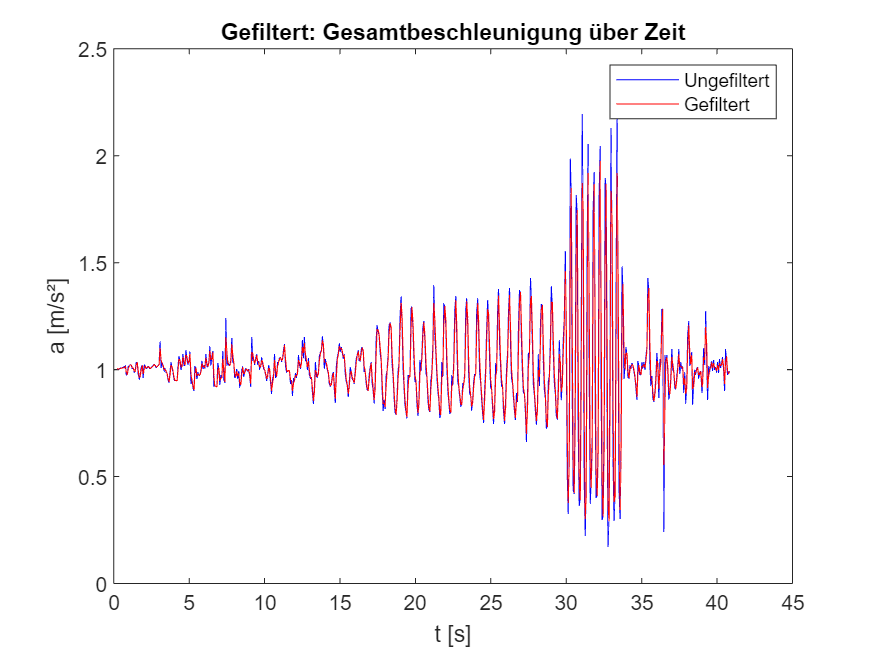

% BESCHLEUNIGUNG: 
runAccel = false;
if runAccel
    figure;
    plot(t, accelerationTotal);
    xlabel('t [s]');
    ylabel('a [m/s²]');
    title('Gesamtbeschleunigung über Zeit');

    figure;
    plot(t, accelerationX);
    xlabel('t [s]');
    ylabel('a_x [m/s²]');
    title('Beschleunigung in x-Richtung über Zeit');

    figure;
    plot(t, accelerationY);
    xlabel('t [s]');
    ylabel('a_y [m/s²]');
    title('Beschleunigung in y-Richtung über Zeit');

    figure;
    plot(t, accelerationZ);
    xlabel('t [s]');
    ylabel('a_z [m/s²]');
    title('Beschleunigung in z-Richtung über Zeit');
end

runFilteredAccel = true;
if runFilteredAccel
    plot(t, accelerationTotal, 'b-', t, filteredAcceleration, 'r-');
    xlabel('t [s]');
    ylabel('a [m/s²]');
    title('Gefiltert: Gesamtbeschleunigung über Zeit');
    legend('Ungefiltert', 'Gefiltert');
end

#### Geschwindigkeit:

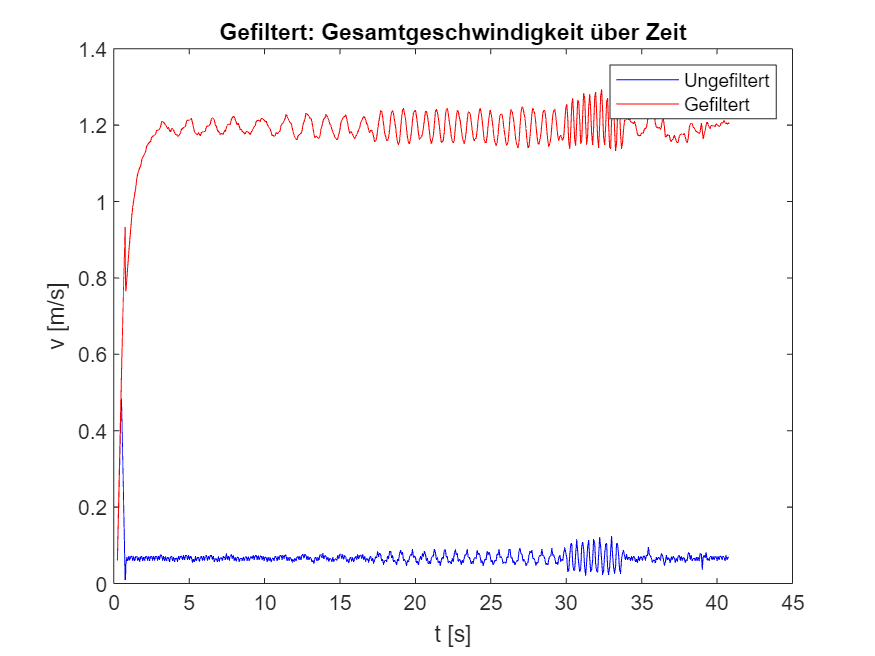

% GESCHWINDIGKEIT:
runVelocity = false;
if runVelocity
    plot(t_mid_velocity, velocity);
    xlabel('t [s]');
    ylabel('v [m/s]');
    title('Gesamtgeschwindigkeit über Zeit');
end

runFilteredVelocity = true;
if runFilteredVelocity
    plot(t_mid_velocity, velocity, 'b-', t_mid_velocity, filteredVelocity, 'r-');
    xlabel('t [s]');
    ylabel('v [m/s]');
    title('Gefiltert: Gesamtgeschwindigkeit über Zeit');
    legend('Ungefiltert', 'Gefiltert');
end

#### Strecke:

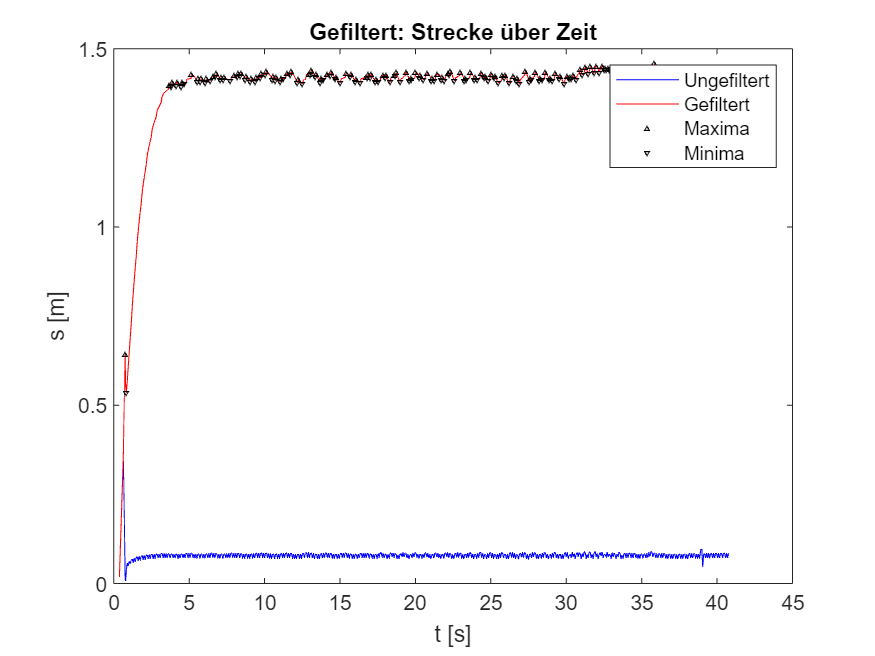

% STRECKE:
runSegment = false;
if runSegment
    plot(t_mid_segment, segment);
    xlabel('t [s]');
    ylabel('s [m]');
    title('Strecke über Zeit');
end

runFilteredSegment = true;
runPeaks = true;
if runFilteredSegment
    plot(t_mid_segment, segment, 'b-', t_mid_segment, filteredSegment, 'r-');
    if runPeaks
        hold on;
        plot(t_mid_segment(maxIdx), maxima, 'k^', 'MarkerSize', 2, 'DisplayName', 'Maxima');
        plot(t_mid_segment(minIdx), minima, 'kv', 'MarkerSize', 2, 'DisplayName', 'Minima');
        hold off;
    end
    xlabel('t [s]');
    ylabel('s [m]');
    title('Gefiltert: Strecke über Zeit');
    if runPeaks
        legend('Ungefiltert', 'Gefiltert', 'Maxima', 'Minima');
    else
        legend('Ungefiltert', 'Gefiltert');
    end
end

#### CCD:

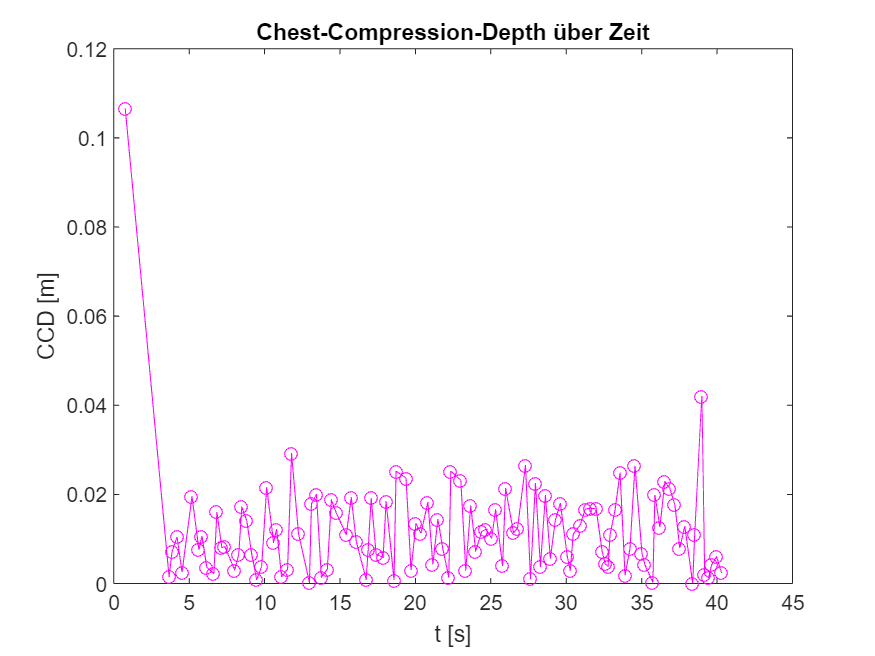

runCCD = true;
if runCCD
    t_ccd = t_mid_segment(maxIdx(1:length(ccd))); 
    plot(t_ccd, ccd, 'm-o', 'LineWidth', 0.5);
    xlabel('t [s]');
    ylabel('CCD [m]');
    title('Chest-Compression-Depth über Zeit');
end